**Sistemas EDO de Primer Orden**

clear;

% Párametros del problema:
t0 = 0, tf = 1

t0 = 0

tf = 1

% Condiciones iniciales:
x10 = 1, x20 = 2

x10 = 1

x20 = 2

**Solución Exacta**

syms x1(t) x2(t)
Dx1 = diff(x1,t);
Dx2 = diff(x2,t);
sol = dsolve(Dx1 == 3*x1 - 5*x2 + t, Dx2 == -2*x2 + 4*x1 - t, x1(0)==1, x2(0)==2)

sol = struct with fields:
    x2: - exp(t/2)*cos((55^(1/2)*t)/2)*((exp(-t/2)*(55*cos((55^(1/2)*t)/2) + 29*55^(1/2)*sin((55^(1/2)*t)/2) - 770*t*cos((55^(1/2)*t)/2) + 42*55^(1/2)*t*sin((55^(1/2)*t)/2)))/1540 - 57/28) - exp(t/2)*sin((55^(1/2)*t)/2)*((17*55^(1/2))/308 - (exp(-t/2...
    x1: - ((5*exp(t/2)*sin((55^(1/2)*t)/2))/8 + (55^(1/2)*exp(t/2)*cos((55^(1/2)*t)/2))/8)*((17*55^(1/2))/308 - (exp(-t/2)*(29*55^(1/2)*cos((55^(1/2)*t)/2) - 55*sin((55^(1/2)*t)/2) + 770*t*sin((55^(1/2)*t)/2) + 42*55^(1/2)*t*cos((55^(1/2)*t)/2)))/154...


sol_x1 = matlabFunction(sol.x1);
sol_x2 = matlabFunction(sol.x2);
tt = t0:0.05:tf;
x1_sol = sol_x1(tt);
x2_sol = sol_x2(tt);

**SEDO - PVI:**

% Funciones del S.EDO:
F = @(t,y) [ 3*y(1) - 5*y(2) + t
            -2*y(2) + 4*y(1) - t ];
% C.I:
y0 = [x10 x20]';
% Paso h:
h = 0.2;

**Solución Numérica con Euler:**

% % function [t_euler,y_euler,FF] = eulerV(F,t0,tf,y0,h)
% t_euler = t0:h:tf; t_euler = t_euler';
% iter = 0:length(t_euler)-1; iter = iter';
% m = length(t_euler);
% n = length(y0);
% y_euler = zeros(m,n);
% FF = zeros(m,n);
% % [ t_euler y_euler FF]
% y_euler(1,:) = y0
% for i = 1:length(t_euler)-1
%     FF(i,:) = F(t_euler(i,1),y_euler(i,:));
%     y_euler(i+1,:) = y_euler(i,:) + h*FF(i,:);
% end

[iter,t_euler,y_euler,FF] = eulerV(F,t0,tf,y0,h);

T = table(iter,t_euler,y_euler,FF,'VariableNames',{'iter','t_euler','y_euler','F(t,y)'});
disp(T)

    iter    t_euler         y_euler              F(t,y)     
    ____    _______    _________________    ________________

     0          0           1          2       -7          0
     1        0.2        -0.4          2      -11       -5.8
     2        0.4        -2.6       0.84    -11.6     -12.48
     3        0.6       -4.92     -1.656    -5.88    -16.968
     4        0.8      -6.096    -5.0496     7.76    -15.085
     5          1      -4.544    -8.0666        0          0



**Gráfica Comparativa:**

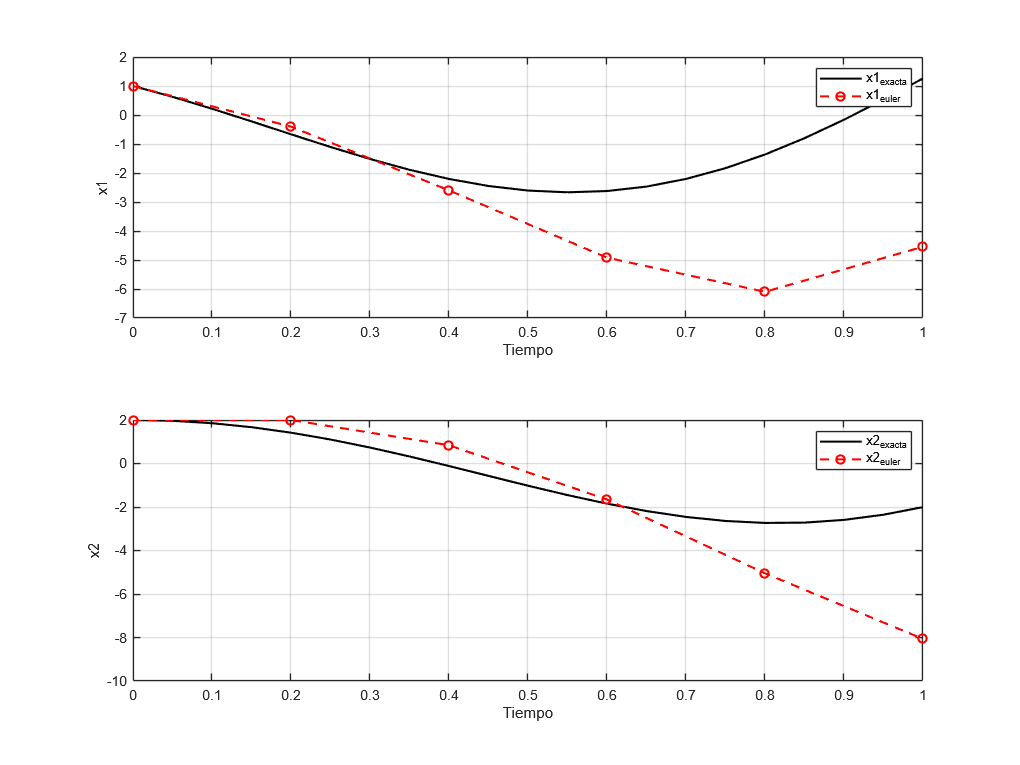

figure(1); clf;

subplot(2,1,1);
plot(tt,x1_sol,'-k','LineWidth',1.5); grid on; hold on;
plot(t_euler,y_euler(:,1),'--or','LineWidth',1.5);
xlabel('Tiempo');
ylabel('x1');
legend('x1_{exacta}','x1_{euler}');

subplot(2,1,2);
plot(tt,x2_sol,'-k','LineWidth',1.5); grid on; hold on;
plot(t_euler,y_euler(:,2),'--or','LineWidth',1.5);
xlabel('Tiempo');
ylabel('x2');
legend('x2_{exacta}','x2_{euler}');

function [iter,t_euler,y_euler,FF] = eulerV(F,t0,tf,y0,h)
    t_euler = t0:h:tf; t_euler = t_euler';
    iter = 0:length(t_euler)-1; iter = iter';
    m = length(t_euler);
    n = length(y0);
    y_euler = zeros(m,n);
    FF = zeros(m,n);
    y_euler(1,:) = y0;
    for i = 1:length(t_euler)-1
        FF(i,:) = F(t_euler(i,1),y_euler(i,:));
        y_euler(i+1,:) = y_euler(i,:) + h*FF(i,:);
    end
end